### The s-domain transfer function in code


$$G(s) = \frac{s+2}{s^2+s+2}$$


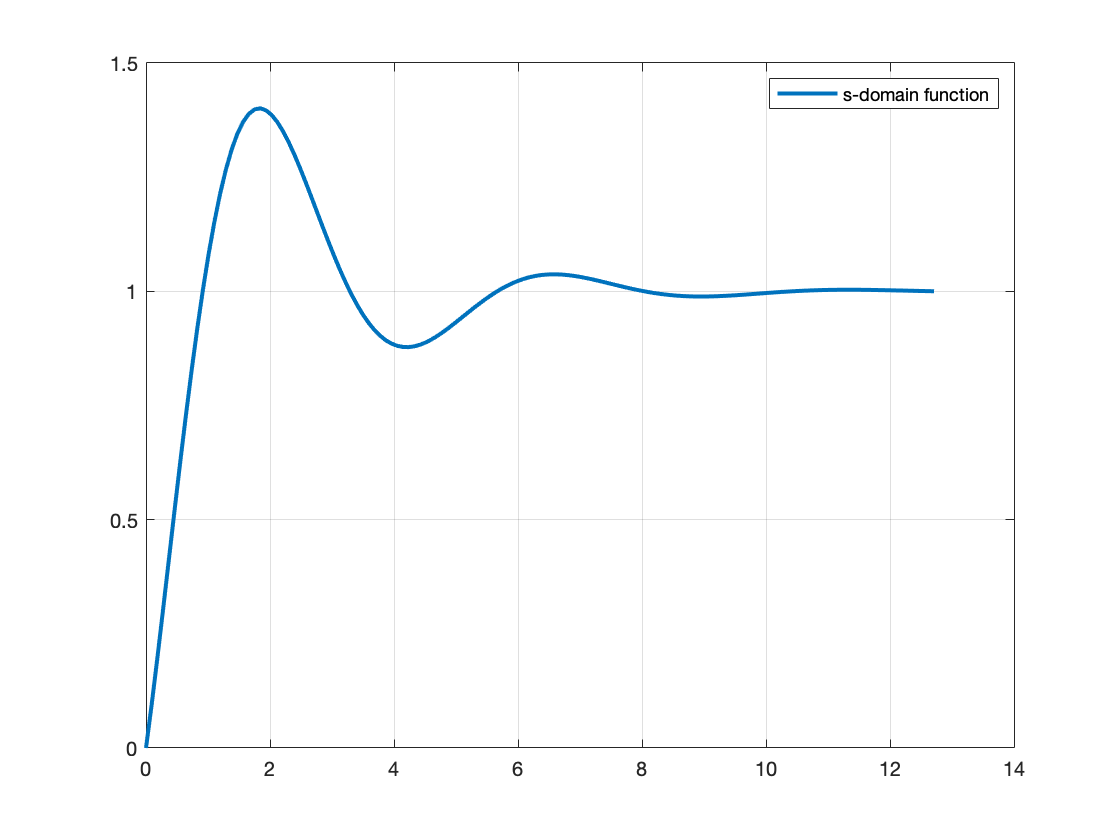


% Define transfer function G
s = tf('s');
G = (s + 2)/ (s^2 + s + 2); 

% Step response
[x, t] = step(G); 

plot(t, x, 'LineWidth', 2);
grid
legend('s-domain function')
hold all

## Method 1: Numerically solve the differential equation


$$\ddot{y}(t)=\dot{u}(t)+2u(t)-\dot{y}(t)-2y(t)$$


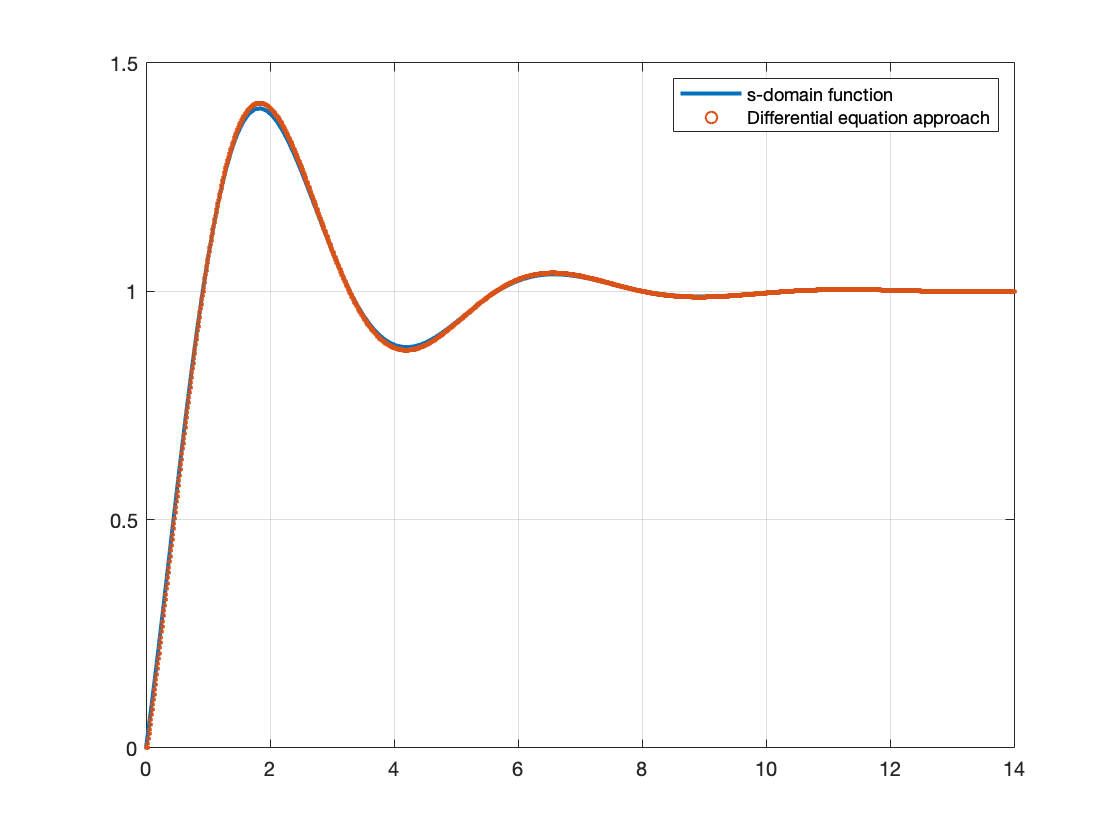

% Build time vector
dt = 0.01;
t = 0:dt:14; 

% Build step input
u = ones(size(t)); 
u(1) = 0; 

% Initial conditions
y0 = 0;
yd0 = 0;
ud0 = 0;

% Predefine the size of the input/ouput vectors
ud = zeros(size(t));
y = zeros(size(t));
yd = zeros(size(t));
ydd = zeros(size(t));

% Step through time and solve the differential equation
for i = 1:length(t)
    if i == 1 
        ud(i) = ud0;
        yd(i) = yd0;
        y(i) = y0;
        ydd(i) = ud(i) + 2*u(i) - yd(i) - 2*y(i);
    else
        ud(i) = (u(i) - u(i-1))/dt;    % ud = du/dt
        yd(i) = yd(i-1) + dt*ydd(i-1); % yd = int(ydd*dt)
        y(i) = y(i-1) + dt*yd(i-1);    %  y = int(yd*dt)
        ydd(i) = ud(i) + 2*u(i) - yd(i) - 2*y(i); % Differential equation
    end
end

scatter(t, y, 3);
legend('s-domain function', 'Differential equation approach')

## Method 2: Convert the transfer function to a state space model


$$\dot{x}(t)=Ax(t)+Bu(t)$$



$$y(t)=Cx(t)+Du(t)$$


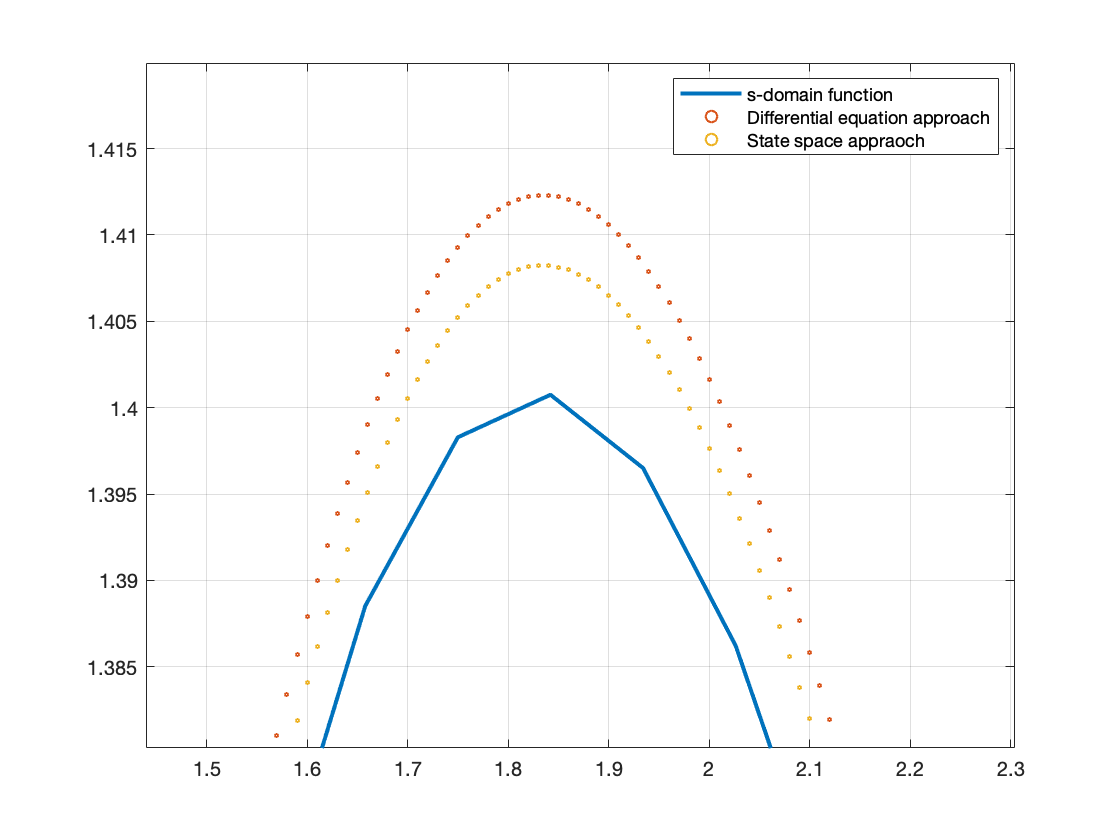

% Build time vector
dt = 0.01;
t = 0:dt:14;

% Build step input
u = ones(size(t)); 
u(1) = 0; 

% State space model
A = [-1, -2; 1, 0];
B = [2; 0];
C = [0.5, 1];
D = 0;

% Initial conditions
x0 = [0; 0];
xd0 = [0; 0];

% Predefine the size of the state/ouput vectors
x = zeros(2,length(t));
xd = zeros(2, length(t));
y = zeros(size(t));

% Step through time and solve the differential equation
for i = 1:length(t)
    if i ==1
        x(:, i) = x0;
        xd(:,i) = A*x0 + B*u(i);
        y(i) = C*x0 + D*u(i);
    else
        x(:,i) = x(:,i-1) + dt*xd(:,i-1); % x = int(xd*dt)
        xd(:,i) = A*x(:,i) + B*u(i);  % State equation
        y(i) = C*x(:,i) + D*u(i);     % Output equation
    end
end

scatter(t, y, 3);
legend('s-domain function', 'Differential equation approach',...
    'State space appraoch')

## Method 3: Convert the transfer function to the z-domain


$$y_i=0.005025u_i+\mathrm{9.95e}{-5}u_{i-1}-0.004925u_{i-2}+1.9899y_{i-1}-0.9901y_{i-2}$$


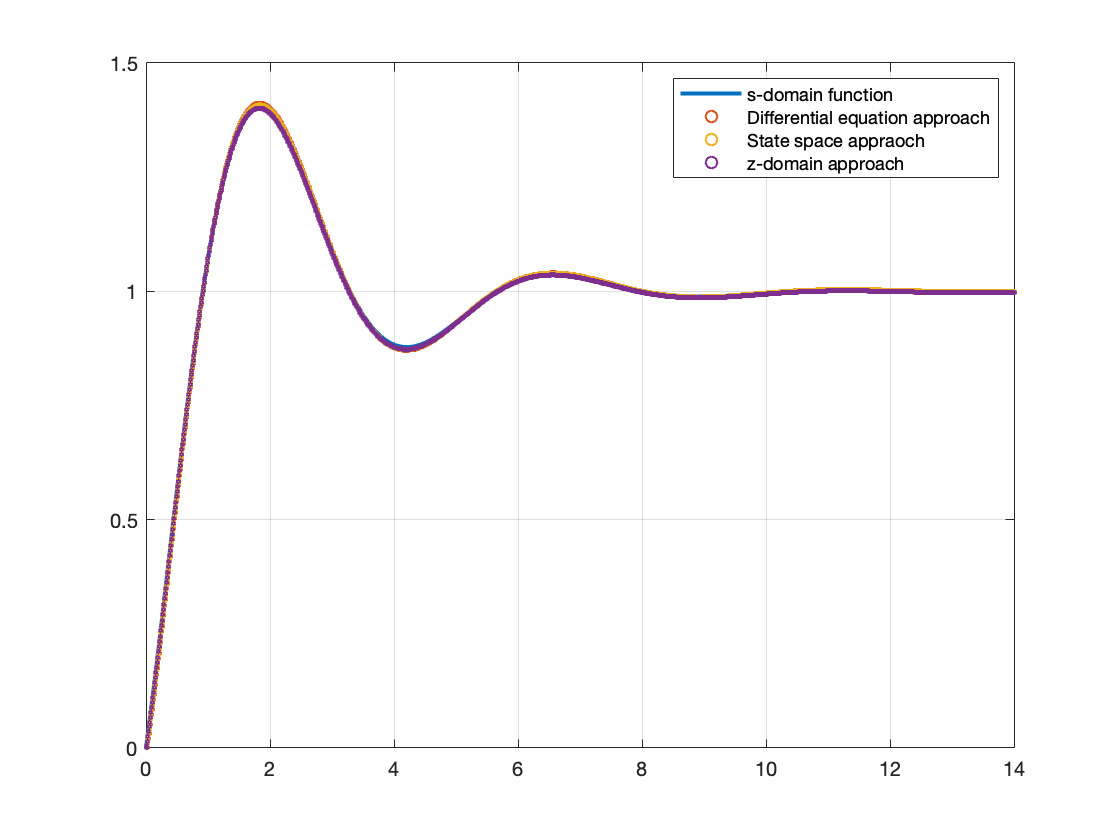

% Build time vector
dt = 0.01;
t = 0:dt:14;

% Build step input
u = ones(size(t)); 
u(1) = 0; 

% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past

% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = 0.005025*u(i) + 9.95e-5 * uk_1 - 0.004925 * uk_2;
        yterms = 1.9899 * yk_1 - 0.9901 * yk_2;
        y(i) = uterms + yterms;      
    elseif i == 2
        uterms = 0.005025*u(i) + 9.95e-5 * u(i-1) - 0.004925 * uk_1;
        yterms = 1.9899 * y(i-1) - 0.9901 * yk_1;
        y(i) = uterms + yterms;    
    else
        uterms = 0.005025*u(i) + 9.95e-5 * u(i-1) - 0.004925 * u(i-2);
        yterms = 1.9899 * y(i-1) - 0.9901 * y(i-2);
        y(i) = uterms + yterms; 
    end
end

scatter(t, y, 3);
legend('s-domain function', 'Differential equation approach',...
    'State space appraoch', 'z-domain approach')